# **CÁLCULO DE FUERZAS INTERNAS EN CABLES DE SUSTENTACIÓN VERTICAL DE PUENTES COLGANTES**

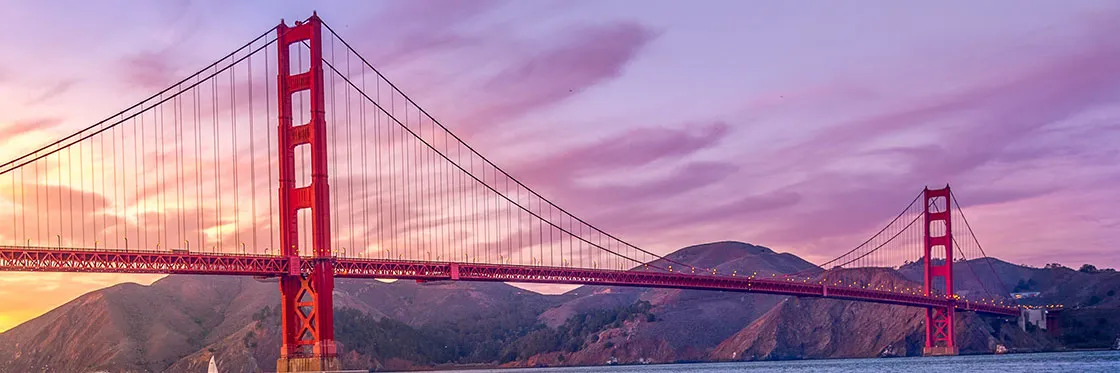

Factor de conversión

meters = 0.305 % pies a metros

meters =    0.305000000000000


centimeters = 30.48 % pies a centimetros

centimeters =   30.480000000000000


Inches = 12 % pies a pulgadas

Inches =     12


F = 1

F =      1


### Datos

% Número de nodos en el cable principal
N = 250

N =    250


% Separación horizontal de los cables verticales (ft)
li = 50*F

li =     50


% Maxima distancia entre el punto más bajo y más alto del cable principal
MAX_CABLE_SAG = 472.2*F

MAX_CABLE_SAG =      4.722000000000000e+02


% Longitud del cable principal
LENGTH_MAIN_SPAN = 4200*F

LENGTH_MAIN_SPAN =         4200


% Fueza horizontal de cada cable (kips)
H = 53467

H =        53467


% Peso (kips/ft)
W = 3.34

W =    3.340000000000000


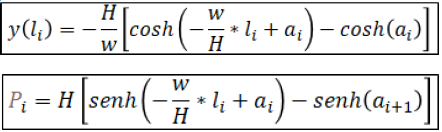

Aproximación de a1

x = [0 LENGTH_MAIN_SPAN/2 LENGTH_MAIN_SPAN]

x =            0        2100        4200


y = [MAX_CABLE_SAG 0 MAX_CABLE_SAG]

y = 	1.0e+02 *

   4.722000000000000                   0   4.722000000000000


p2 = polyfit(x, y, 2)

p2 = 	1.0e+02 *

   0.000001070748299  -0.004497142857143   4.721999999999999


yl1 = polyval(p2, 0) - polyval(p2, li)

yl1 =   22.218027210884316


f = @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl1)

f = function_handle with value:
    @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl1)


xx = linspace(0.41, 0.45)

xx =    0.410000000000000   0.410404040404040   0.410808080808081   0.411212121212121   0.411616161616162   0.412020202020202   0.412424242424242   0.412828282828283   0.413232323232323   0.413636363636364   0.414040404040404   0.414444444444444   0.414848484848485   0.415252525252525   0.415656565656566   0.416060606060606   0.416464646464646   0.416868686868687   0.417272727272727   0.417676767676768   0.418080808080808   0.418484848484848   0.418888888888889   0.419292929292929   0.419696969696970   0.420101010101010   0.420505050505050   0.420909090909091   0.421313131313131   0.421717171717172   0.422121212121212   0.422525252525253   0.422929292929293   0.423333333333333   0.423737373737374   0.424141414141414   0.424545454545455   0.424949494949495   0.425353535353535   0.425757575757576   0.426161616161616   0.426565656565657   0.426969696969697   0.427373737373737   0.427777777777778   0.428181818181818   0.428585858585859   0.428989898989899   0.429393939393939   0.4297979797

yy = f(xx)

yy =   -1.223545724491998  -1.201633355895716  -1.179717556409482  -1.157798322439692  -1.135875650421173  -1.113949536767429  -1.092019977902620  -1.070086970243803  -1.048150510215141  -1.026210594230136  -1.004267218712950  -0.982320380073535  -0.960370074736048  -0.938416299113996  -0.916459049624429  -0.894498322684406  -0.872534114707427  -0.850566422103437  -0.828595241293048  -0.806620568686203  -0.784642400696409  -0.762660733733604  -0.740675564214847  -0.718686888546532  -0.696694703138604  -0.674699004401006  -0.652699788747242  -0.630697052580150  -0.608690792309673  -0.586681004342207  -0.564667685094804  -0.542650830963193  -0.520630438357319  -0.498606503672914  -0.476579023327027  -0.454547993718947  -0.432513411251509  -0.410475272327549  -0.388433573353463  -0.366388310724972  -0.344339480848475  -0.322287080119697  -0.300231104937918  -0.278171551709534  -0.256108416833825  -0.234041696695861  -0.211971387705582  -0.189897486258719  -0.167819988747443  -0.1457388915

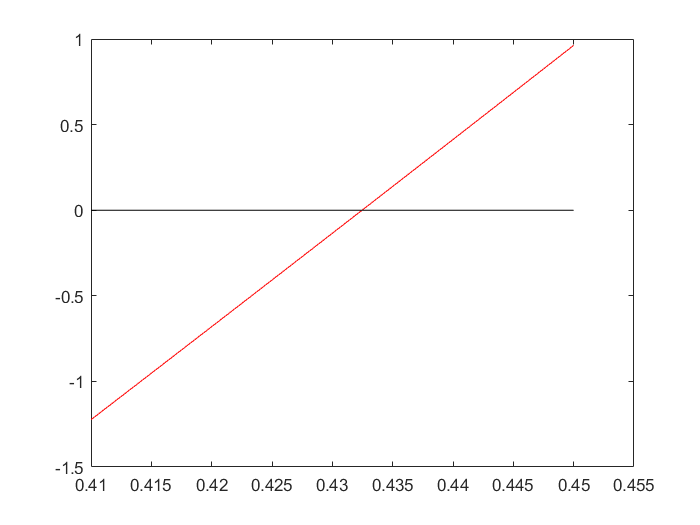

plot(xx, yy, 'r', xx, zeros(length(xx)), 'k')

a1 = biseccion(f, 0.4, 0.5, 0, 120)

Se necesitan como máximo Inf iteraciones


a1 =    0.432463058418853


Aproximacion de a2

yl2 = polyval(p2, li) - polyval(p2, 2*li)

yl2 =   21.682653061224471


f = @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2)

f = function_handle with value:
    @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2)


xx = linspace(0.41, 0.45)

xx =    0.410000000000000   0.410404040404040   0.410808080808081   0.411212121212121   0.411616161616162   0.412020202020202   0.412424242424242   0.412828282828283   0.413232323232323   0.413636363636364   0.414040404040404   0.414444444444444   0.414848484848485   0.415252525252525   0.415656565656566   0.416060606060606   0.416464646464646   0.416868686868687   0.417272727272727   0.417676767676768   0.418080808080808   0.418484848484848   0.418888888888889   0.419292929292929   0.419696969696970   0.420101010101010   0.420505050505050   0.420909090909091   0.421313131313131   0.421717171717172   0.422121212121212   0.422525252525253   0.422929292929293   0.423333333333333   0.423737373737374   0.424141414141414   0.424545454545455   0.424949494949495   0.425353535353535   0.425757575757576   0.426161616161616   0.426565656565657   0.426969696969697   0.427373737373737   0.427777777777778   0.428181818181818   0.428585858585859   0.428989898989899   0.429393939393939   0.4297979797

yy = f(xx)

yy =   -0.688171574832154  -0.666259206235871  -0.644343406749638  -0.622424172779848  -0.600501500761329  -0.578575387107584  -0.556645828242775  -0.534712820583959  -0.512776360555296  -0.490836444570292  -0.468893069053106  -0.446946230413690  -0.424995925076203  -0.403042149454151  -0.381084899964584  -0.359124173024561  -0.337159965047583  -0.315192272443593  -0.293221091633203  -0.271246419026358  -0.249268251036565  -0.227286584073759  -0.205301414555002  -0.183312738886688  -0.161320553478760  -0.139324854741162  -0.117325639087397  -0.095322902920305  -0.073316642649829  -0.051306854682363  -0.029293535434959  -0.007276681303349   0.014743711302525   0.036767645986931   0.058795126332818   0.080826155940898   0.102860738408335   0.124898877332296   0.146940576306381   0.168985838934873   0.191034668811369   0.213087069540148   0.235143044721926   0.257202597950311   0.279265732826019   0.301332452963983   0.323402761954263   0.345476663401126   0.367554160912402   0.3896352580

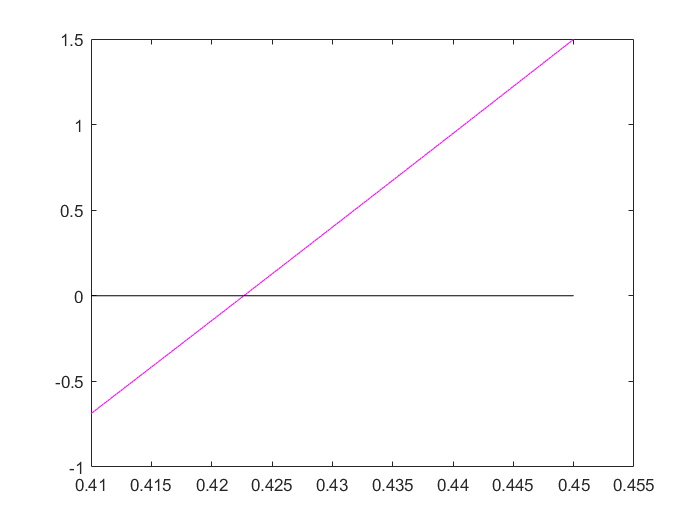

plot(xx, yy, 'm', xx, zeros(length(xx)), 'k')

a2 = biseccion(f, 0.4, 0.5, 0, 120)

Se necesitan como máximo Inf iteraciones


a2 =    0.422658775643696


Aproximación de P1

P = @(l) (H*(sinh((-W/H)*l + a1) - sinh(a2)))

P = function_handle with value:
    @(l)(H*(sinh((-W/H)*l+a1)-sinh(a2)))


xs = linspace(0, 84);
% plot(xs, P(xs), 'b',50, 572.5, 'ro')
P(0)

ans =      5.728568520082395e+02


function [R, z]=biseccion(f, a, b, tol, maxiter)
    if f(a) * f(b) > 0
        z = [];
        fprintf("No se puede asegurar que existe una raíz en este intervalo.");
        return;
    end
    c = (a + b) / 2;
    error = (b - a) / 2;
    n = 0;
    z = [n a b c f(a) f(b) f(c) error];
    N = ceil(log((b-a)/(2*tol)) / log(2));
    fprintf("Se necesitan como máximo %d iteraciones\n", N);
    while error > tol && n < maxiter
        n = n + 1;
        if f(a) * f(c) <= 0
            b = c;
        else
            a = c;  
        end
        c = (a + b) / 2;
        error = (b - a) / 2;
        z = [z; n a b c f(a) f(b) f(c) error];
    end
    z = array2table(z, 'VariableNames', {'Iteration', 'a', 'b', 'c', 'f(a)', 'f(b)', 'f(c)', 'Ea'});
    R = z.c(end);
end


Newton 

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = inline(subs(df),'x');
    z = [x0];
    error = 1;
    while error>Tol
        x1 = x0-f(x0)/dfu(x0);
        z = [z;x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end